# 2. Working with Image Data

## 2.1 Intro

這章的情境是：我們如何透過衛星影像，去觀察、量化，冰川融化的情形？

提供的資料，是 1980 年 和 2011 年 的冰川照片 (為 indexed images)

我們要學的是：

- load images

- visualize images

- extract metadata

- perform calculation

- binarize images

## 2.2 Loading, Displaying, and Saving Different Image Types

matlab 可以支援的 image data type 如下表 (可參考 [官網](https://www.mathworks.com/help/matlab/import_export/supported-file-formats-for-import-and-export.html))

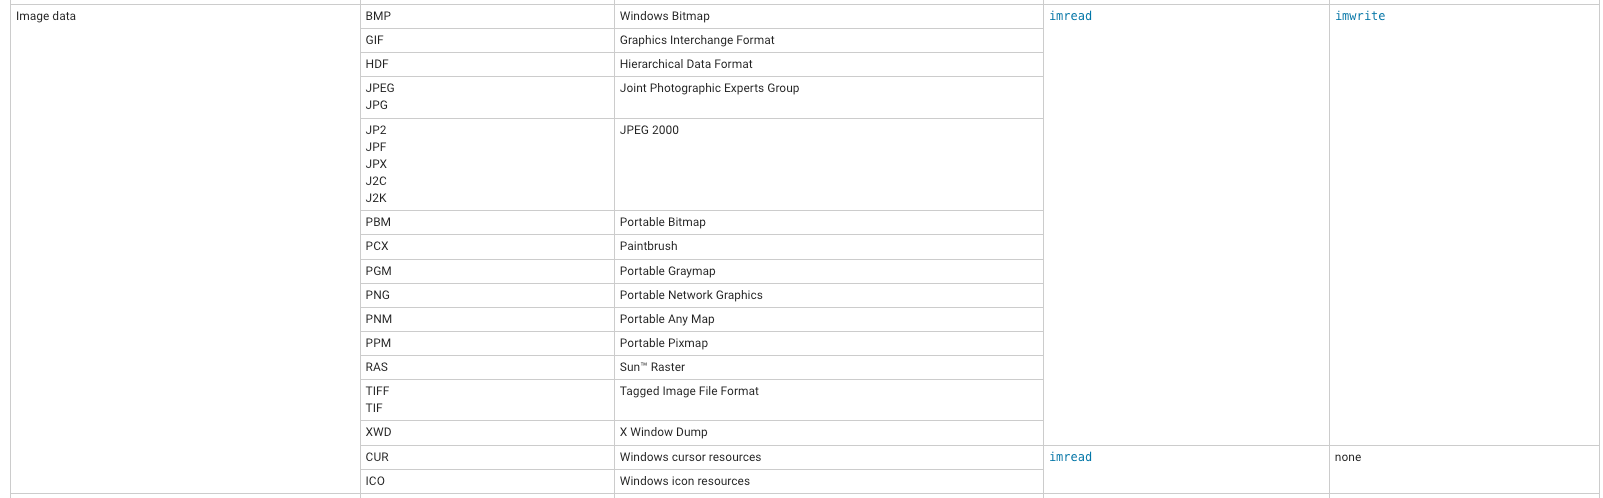

最常見的，就是 grayscale, RGB，和 Indexed imags，官網整理如下：

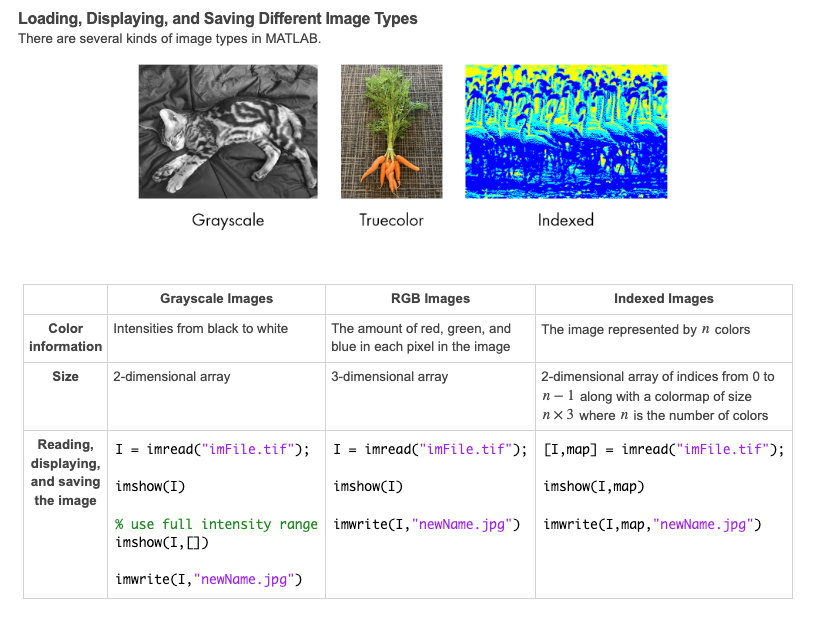

上面的灰階和 RGB 都很熟了，就不練習了。主要是 indexed images 的部分，比較不熟。

他的概念是，如果我用 RGB，那我總共會有 256x256x256 種顏色。但實在太多不需要的顏色了。

所以，indexed images 的做法，是把一張影像，只用 n 種顏色描述。例如，n = 10 種顏色好了。

接著，一張影像如果是 512x512 的 shape，那現在每個 element，就都是 0~9 的數字 (因為 n = 10，有 10 種顏色，就用 0~9 當代表)

那有了這張 512x512 的 index image 還不夠，因為我不知道 0 代表什麼顏色， 1 代表什麼顏色，．．．。所以，會再另存一個 10x3 的 color map array

每一列就是顏色代號 (所以有 10 列)，然後 3 行就是 RGB，這樣我就知道代號 0 的顏色，他的 RGB 分別是多少，就知道他的顏色了。

來做練習吧：

[glacier1980,map1980] = imread("imgs/bearGlacier1980.png");
glacier1980 % 2-d array，每個 element 都是顏色代碼

glacier1980 = 1121×1502 uint8 matrix
    2    2   11    2   11    2   11    2   11    2   11    2   11   11   11   11   11   11   11   11   11   11   11   11   11   11   11   11   11   11   11   11    2   11   11    2    2   11    2   11    2   11   11   11   11   11   11   11   11    4
    2   11    2   11   11   11   11   11   11   11   11   11   11    2   11   11   11   11   11   11    4   11    4   11    4   11   11   11   11   11   11   11   11    2    2   11   11    2   11    2   11    2    2   11   11   11   11   11    4    4
    2    2   11    2   11    2    2   11    2    2   11    2   11   11   11   11   11   11   11   11   11   11   11   11   11   11   11   11   11   11    2   11    2   11   11    2    2   11    2   11   11   11   11    2   11   11   11   11   11    4
   11   11   11    2    2   11   11   11   11   11   11   11   11    2   11    2   11   11   11   11   11    4   11   11    4   11   11   11   11   11   11    2   11    2    2   11    2    2   11    2    2    2

map1980 % row數表示總共有幾種顏色， colum 則分別代表 RGB，可知該列的代表色是什麼

map1980 =     0.0784    0.1137    0.1490
    0.5451    0.6235    0.6863
    0.8157    0.8784    0.8980
    0.3373    0.3725    0.3922
    0.9216    0.9451    0.9529
    0.2275    0.2431    0.2510
    0.6431    0.7647    0.8627
    0.4431    0.4980    0.5373
    0.1216    0.1765    0.2431
    0.9608    0.9725    0.9725


imshow(glacier1980,map1980) % show image 就需要兩個合在一起才能 show

格式要轉換，可用這些 function

- ind2gray: index 影像轉 灰階

- rgb2gray: rgb 轉 灰階

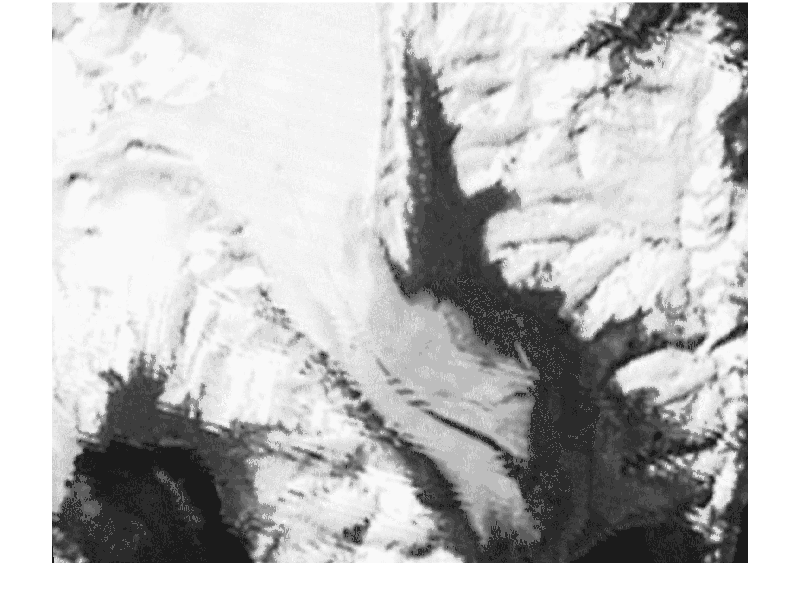

gs1980 = ind2gray(glacier1980,map1980);
imshow(gs1980)

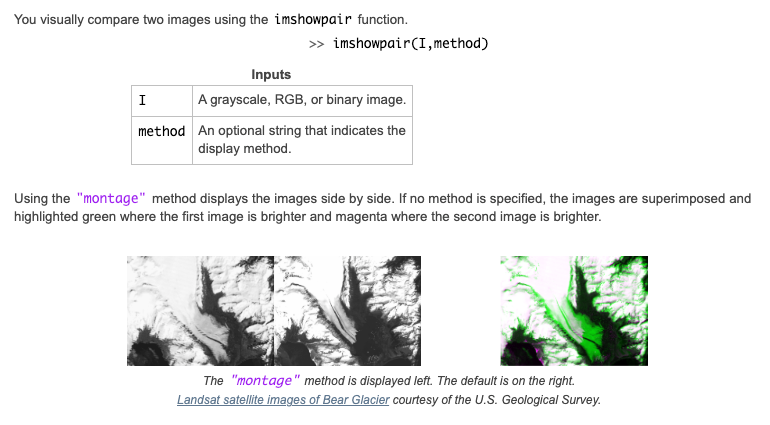

可知，如果要比對兩張影像，就用 `imshowpair(I, method)` 這個 function

但記得，只支援 灰階, RGB, binary image, 所以我要先將我的 index image 轉格式：

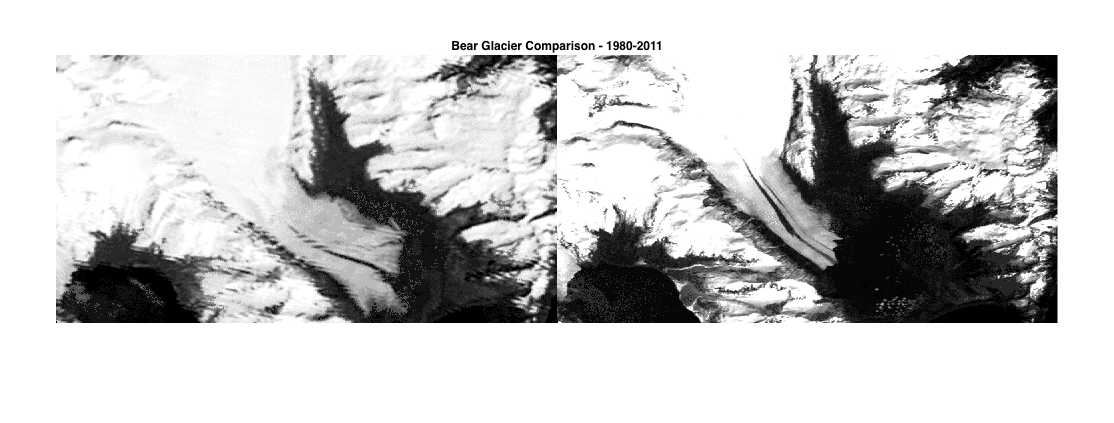

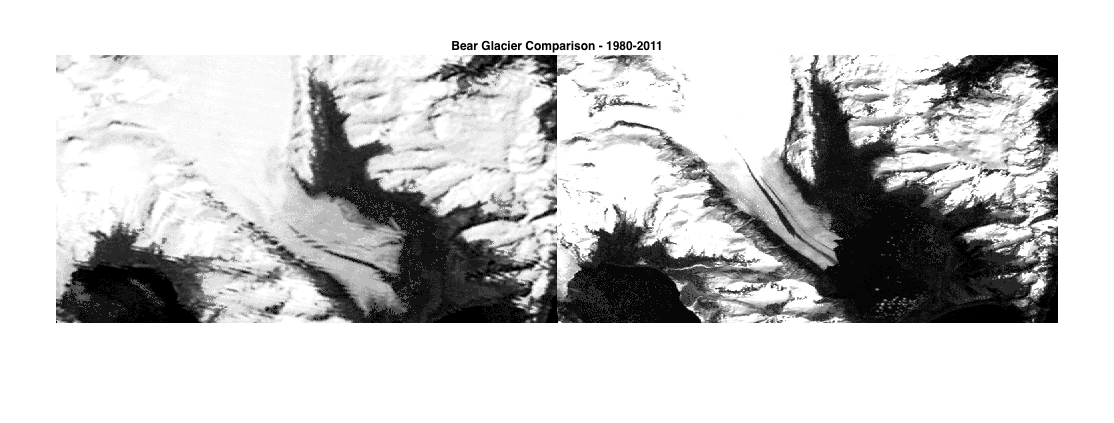

[glacier1980,map1980] = imread("imgs/bearGlacier1980.png");
[glacier2011,map2011] = imread("imgs/bearGlacier2011.png");

gs1980 = ind2gray(glacier1980,map1980);
gs2011 = ind2gray(glacier2011,map2011);

imshowpair(gs1980,gs2011,"montage")
title("Bear Glacier Comparison - 1980-2011")

最後，我們如果把轉換後的灰階圖，存成新影像，他到時候讀進來就會是灰階圖。

如果把indexed image，存成新影像，他到時候讀進來就還是會是 indexed image

imwrite(gs1980, 'imgs/gs1980.png'); % 寫 灰階/RGB 影像
gs1980_read = imread('imgs/gs1980.png');
imshow(gs1980_read)
imwrite(glacier1980,map1980, 'glacier1980_write.png');

pwd

ans = '/Volumes/GoogleDrive/我的雲端硬碟/0.codepool_matlab/matlab_img_processing/img_processing/ch2_working_with_img_data'

dd

tt = imread('imgs/gs1980.png')

tt = 1121×1502 uint8 matrix
   220   220   232   220   232   220   232   220   232   220   232   220   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   220   232   232   220   220   232   220   232   220   232   232   232   232   232   232   232   232   239
   220   232   220   232   232   232   232   232   232   232   232   232   232   220   232   232   232   232   232   232   239   232   239   232   239   232   232   232   232   232   232   232   232   220   220   232   232   220   232   220   232   220   220   232   232   232   232   232   239   239
   220   220   232   220   232   220   220   232   220   220   232   220   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   220   232   220   232   232   220   220   232   220   232   232   232   232   220   232   232   232   232   232   239
   232   232   232   220   220   232   232   232   232   232   232   

tt_im2double = im2double(tt);
imwrite(tt_im2double, "tt_im2double.png")

# Extracting Image File Information

這一節就在講如何取得影像的 meta data

用到的 function 整理如下：

範例：

% 取 metadata
info1980 = imfinfo("imgs/bearGlacier1980.png") % 會是個 struct array, 裡面就有 Filename, CreationTime... 等資訊

info1980 = struct with fields:
                  Filename: '/Volumes/GoogleDrive/我的雲端硬碟/0.codepool_matlab/matlab_img_processing/img_processing/ch2_working_with_img_data/imgs/bearGlacier1980.png'
               FileModDate: '30-Jun-2020 08:45:48'
                  FileSize: 364373
                    Format: 'png'
             FormatVersion: []
                     Width: 1502
                    Height: 1121
                  BitDepth: 8
                 ColorType: 'indexed'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: [20×3 double]
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
            

taken1980 = info1980.CreationTime % 結果會是 '05-Jun-1980 00:00:00' 這種字串

taken1980 = '05-Jun-1980 00:00:00'

info2011 = imfinfo("imgs/bearGlacier2011.png")

info2011 = struct with fields:
                  Filename: '/Volumes/GoogleDrive/我的雲端硬碟/0.codepool_matlab/matlab_img_processing/img_processing/ch2_working_with_img_data/imgs/bearGlacier2011.png'
               FileModDate: '30-Jun-2020 08:45:48'
                  FileSize: 356928
                    Format: 'png'
             FormatVersion: []
                     Width: 1502
                    Height: 1121
                  BitDepth: 8
                 ColorType: 'indexed'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: [20×3 double]
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
            

taken2011 = info2011.CreationTime

taken2011 = '13-May-2011 00:00:00'

% 轉成時間格式，
d1 = datetime(taken1980);
d2 = datetime(taken2011);

% 看分別是該年的第幾天
dayOf1980 = day(d1,"dayofyear")

dayOf1980 = 157

dayOf2011 = day(d2,"dayofyear")

dayOf2011 = 133

% 都是春天的階段，但差幾天？
dayOf1980 - dayOf2011

ans = 24

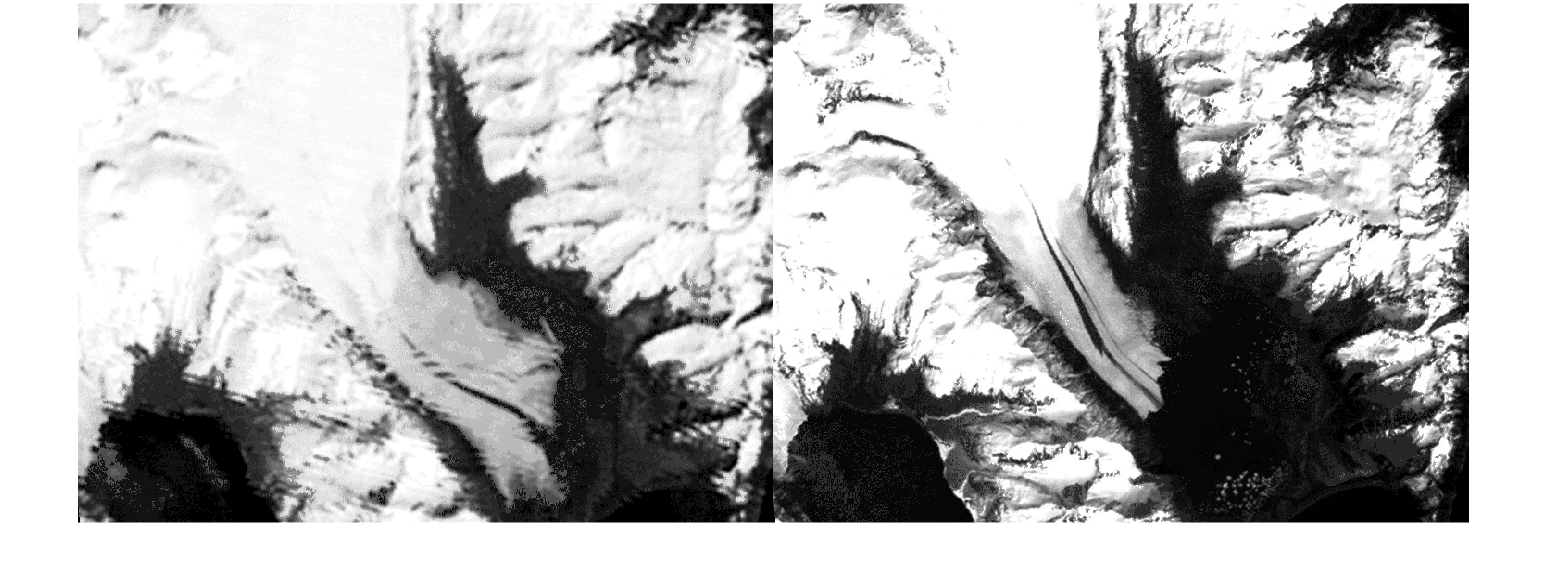

[glacier1980,map80] = imread("imgs/bearGlacier1980.png");
gs1980 = ind2gray(glacier1980,map80);
gs1980 = im2double(gs1980);

[glacier2011,map11] = imread("imgs/bearGlacier2011.png");
gs2011 = ind2gray(glacier2011,map11);
gs2011 = im2double(gs2011);

diffIce = gs1980 - gs2011;
diffIce = rescale(diffIce);
imshowpair(gs1980,gs2011,"montage")

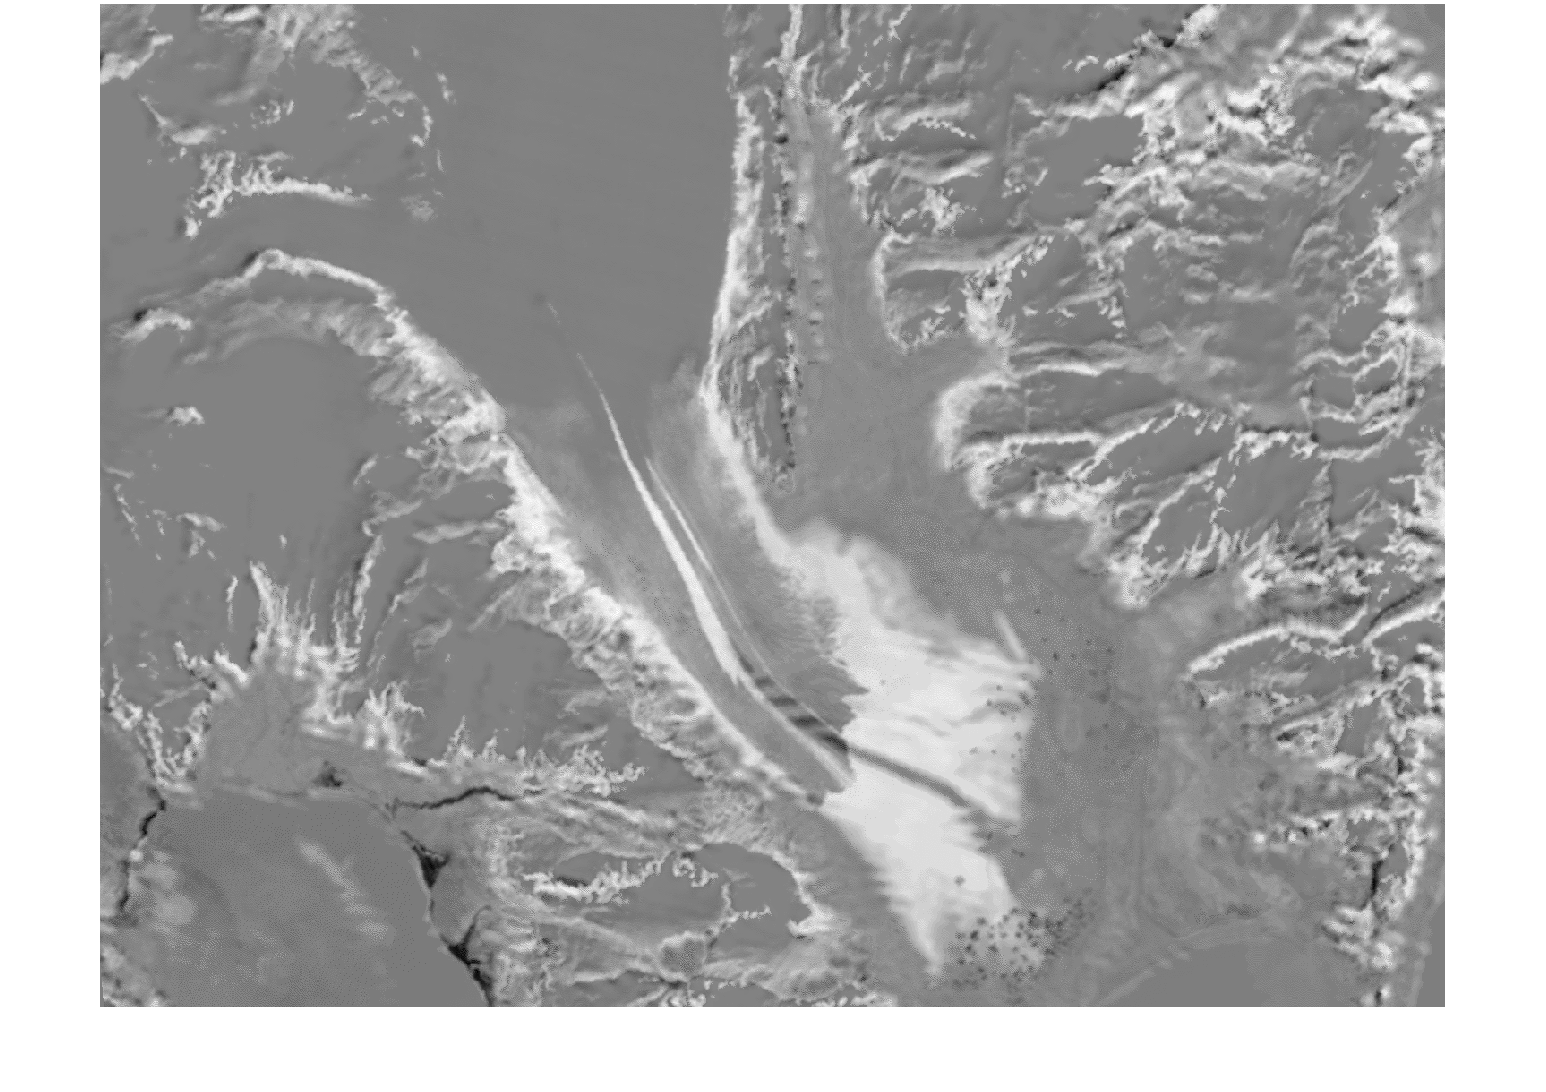

imshow(diffIce)

比較白色的地方，表示 1980 是 ice，但到 2011 已經融化的區域。

比較黑色的地方，表示 1980 是水，但在 2011 是冰的地方

灰色，表示兩個年份差不多的地方

如果要更清楚一點，可以做 thresholding，以 0.7 當門檻，超過就是 1 ，沒超過就是 0，那就可以凸顯冰川融化的地區：

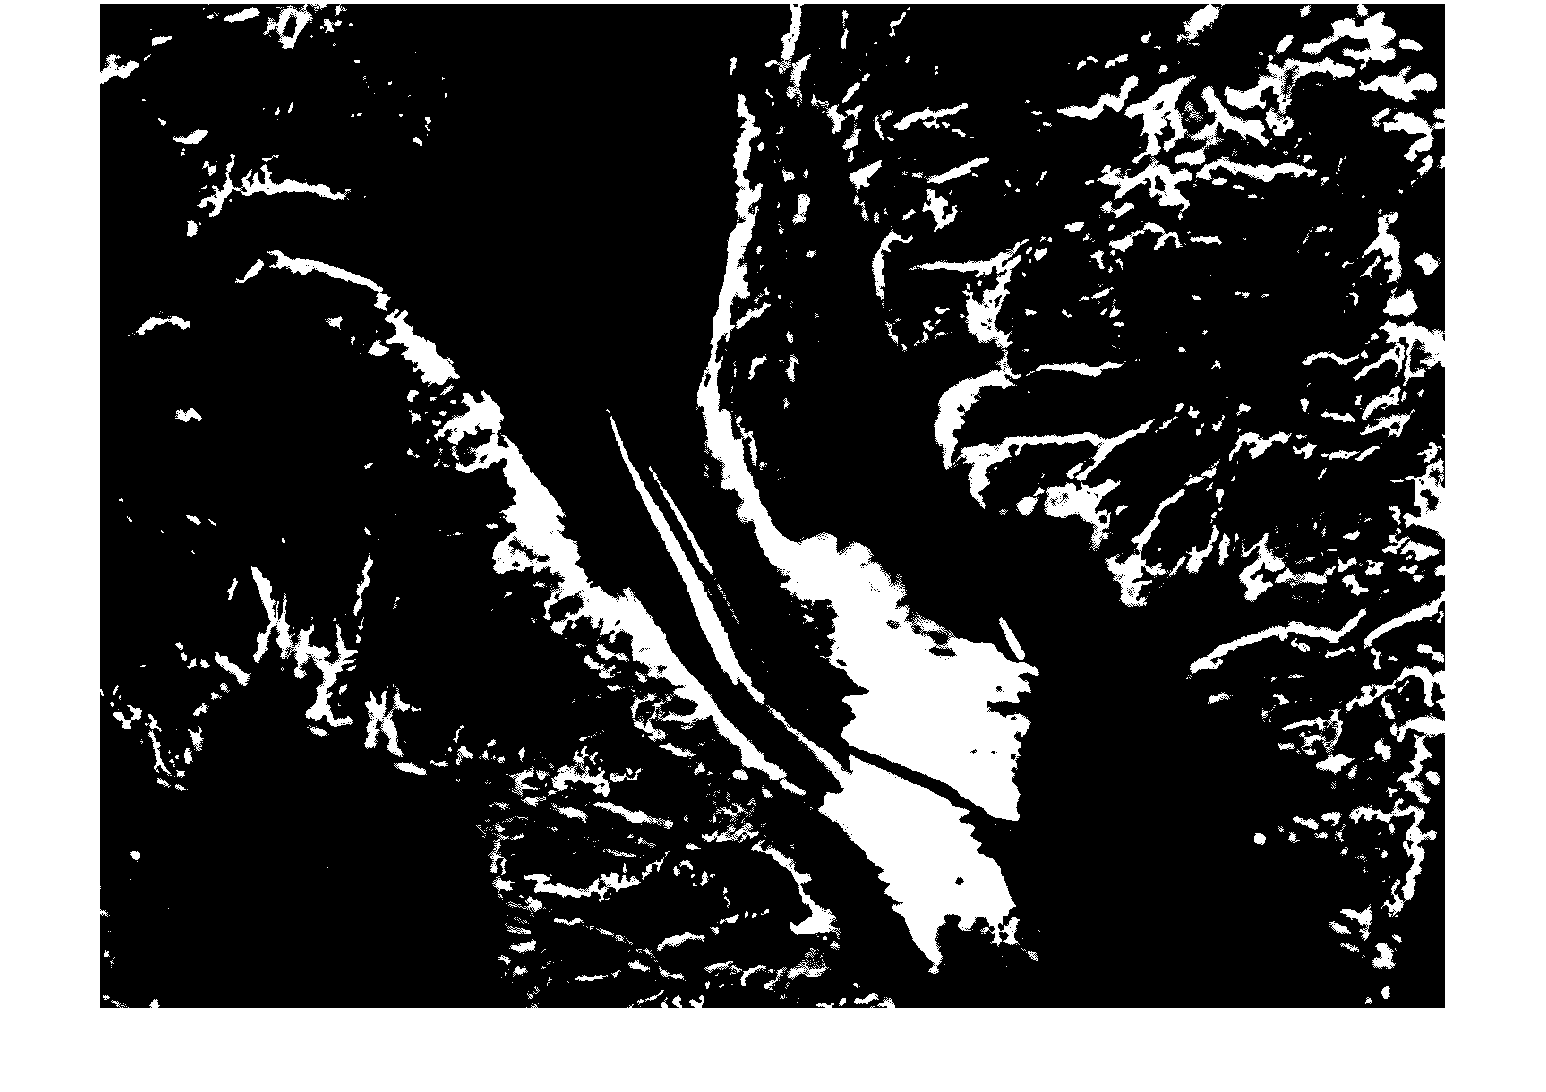

ice1980 = diffIce > 0.7;
imshow(ice1980)

同樣的方式，可以看看 2011 新長出的冰川的位置

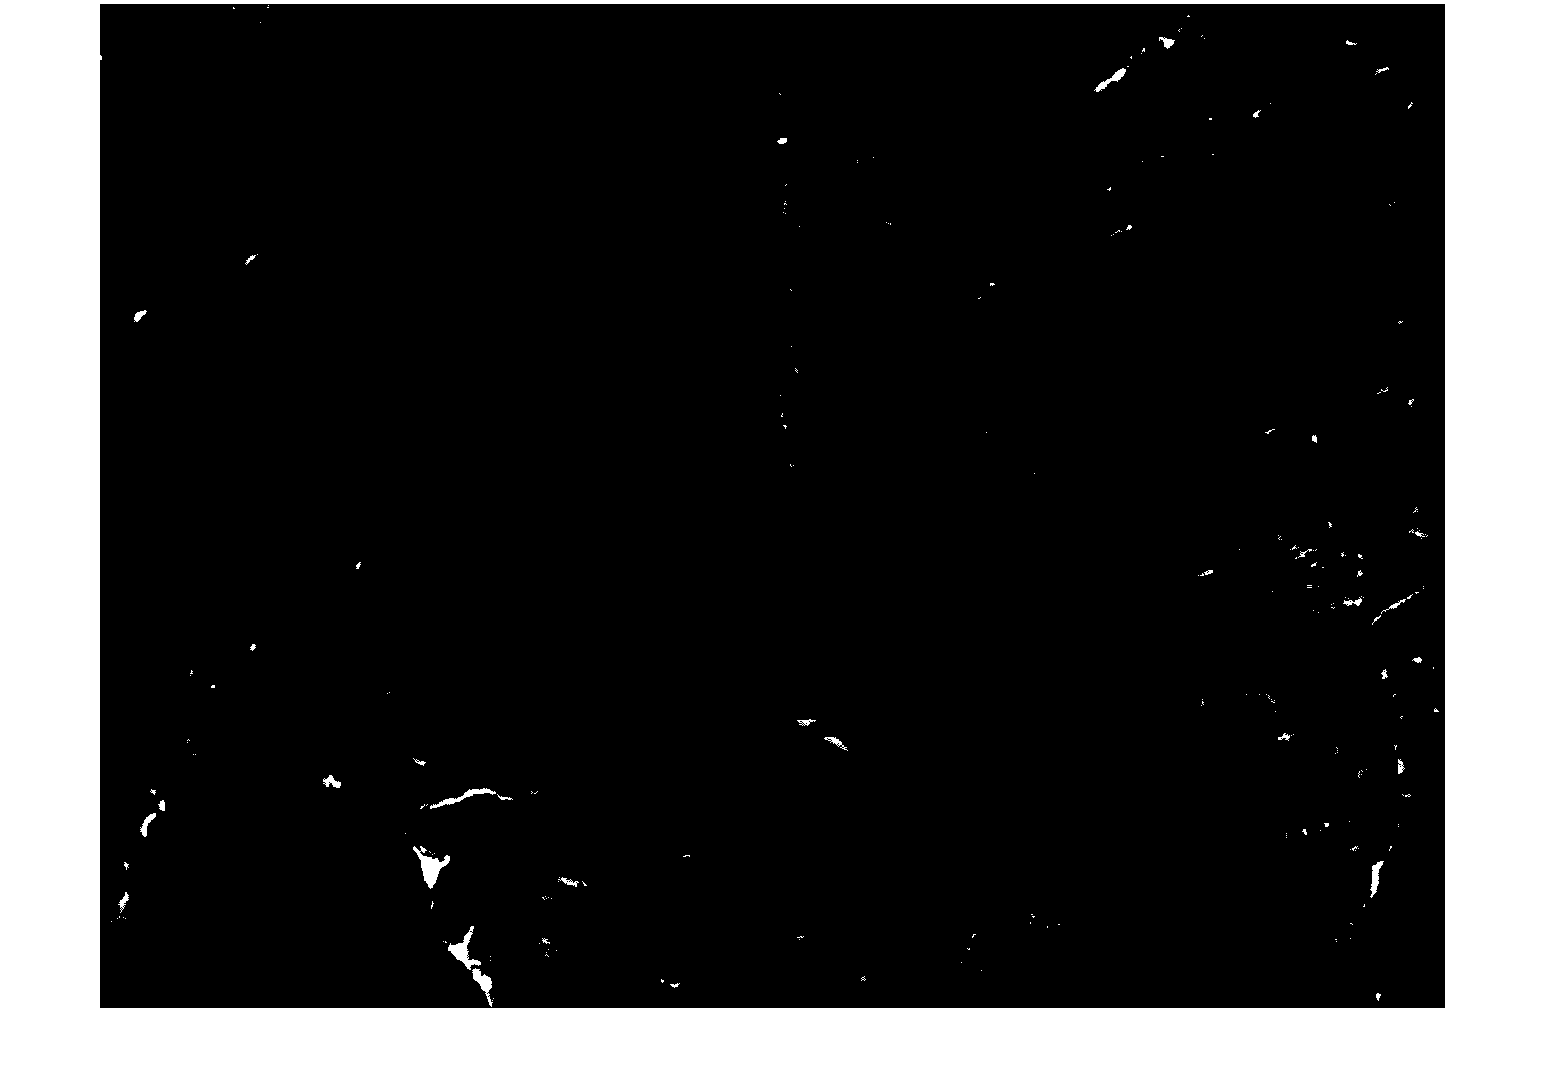

ice2011 = diffIce < 0.3;
imshow(ice2011)

如果想知道，2011 時，冰川融化的比例有多少，可以這樣做：

melt = nnz(ice1980)/numel(ice1980) % 總像素點中，有多少相素點的值是 1 (i.e. 1980照片 - 2011照片後，差值 > 0.7)

melt = 0.1325

再看看另一種做法。

我們可以先用二值化，做出一個 mask

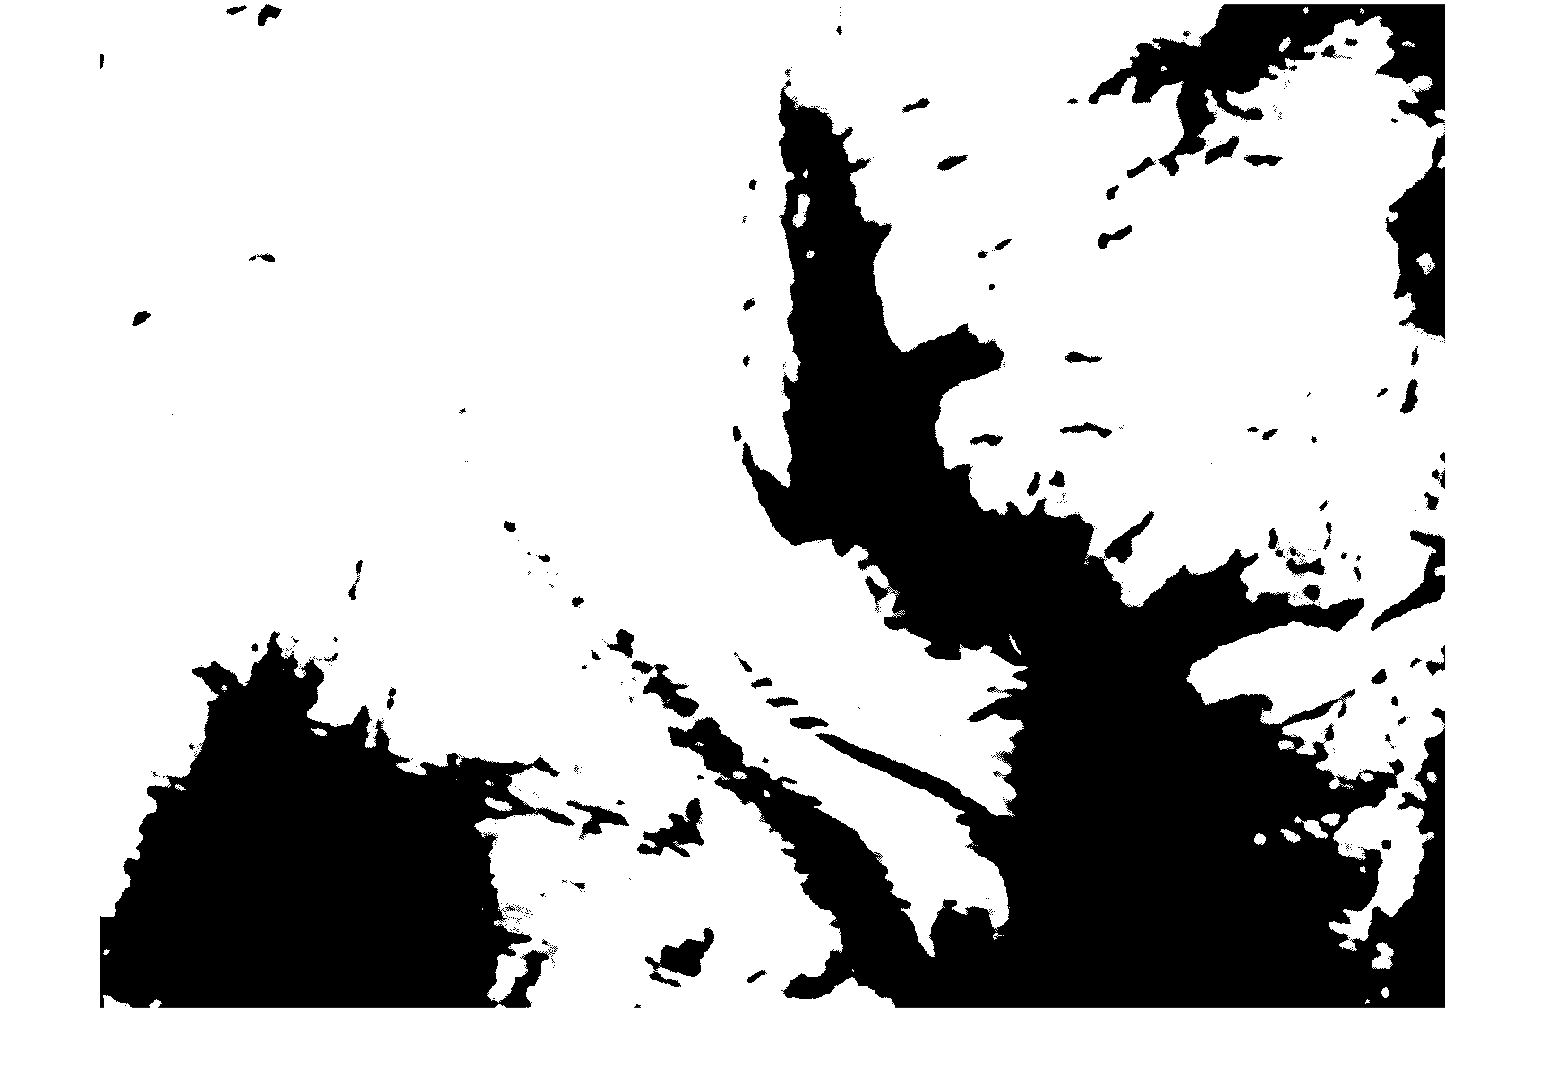

bw1980 = imbinarize(gs1980); % 就是做自動化的 global thresholding, 得到 logical 的 2-d array
imshow(bw1980)

然後，用 `imoverlay(target影像, mask)`，他會把 target影像中， mask 被標為 true 的位置，著色成黃色

也就是，不管 target影像是灰階或RGB，他都把對應位置轉成 RGB 的黃色

所以，看起來就是這樣：

glacier = imoverlay(gs1980,bw1980);
size(gs1980)

ans =         1121        1502


size(glacier)

ans =         1121        1502           3


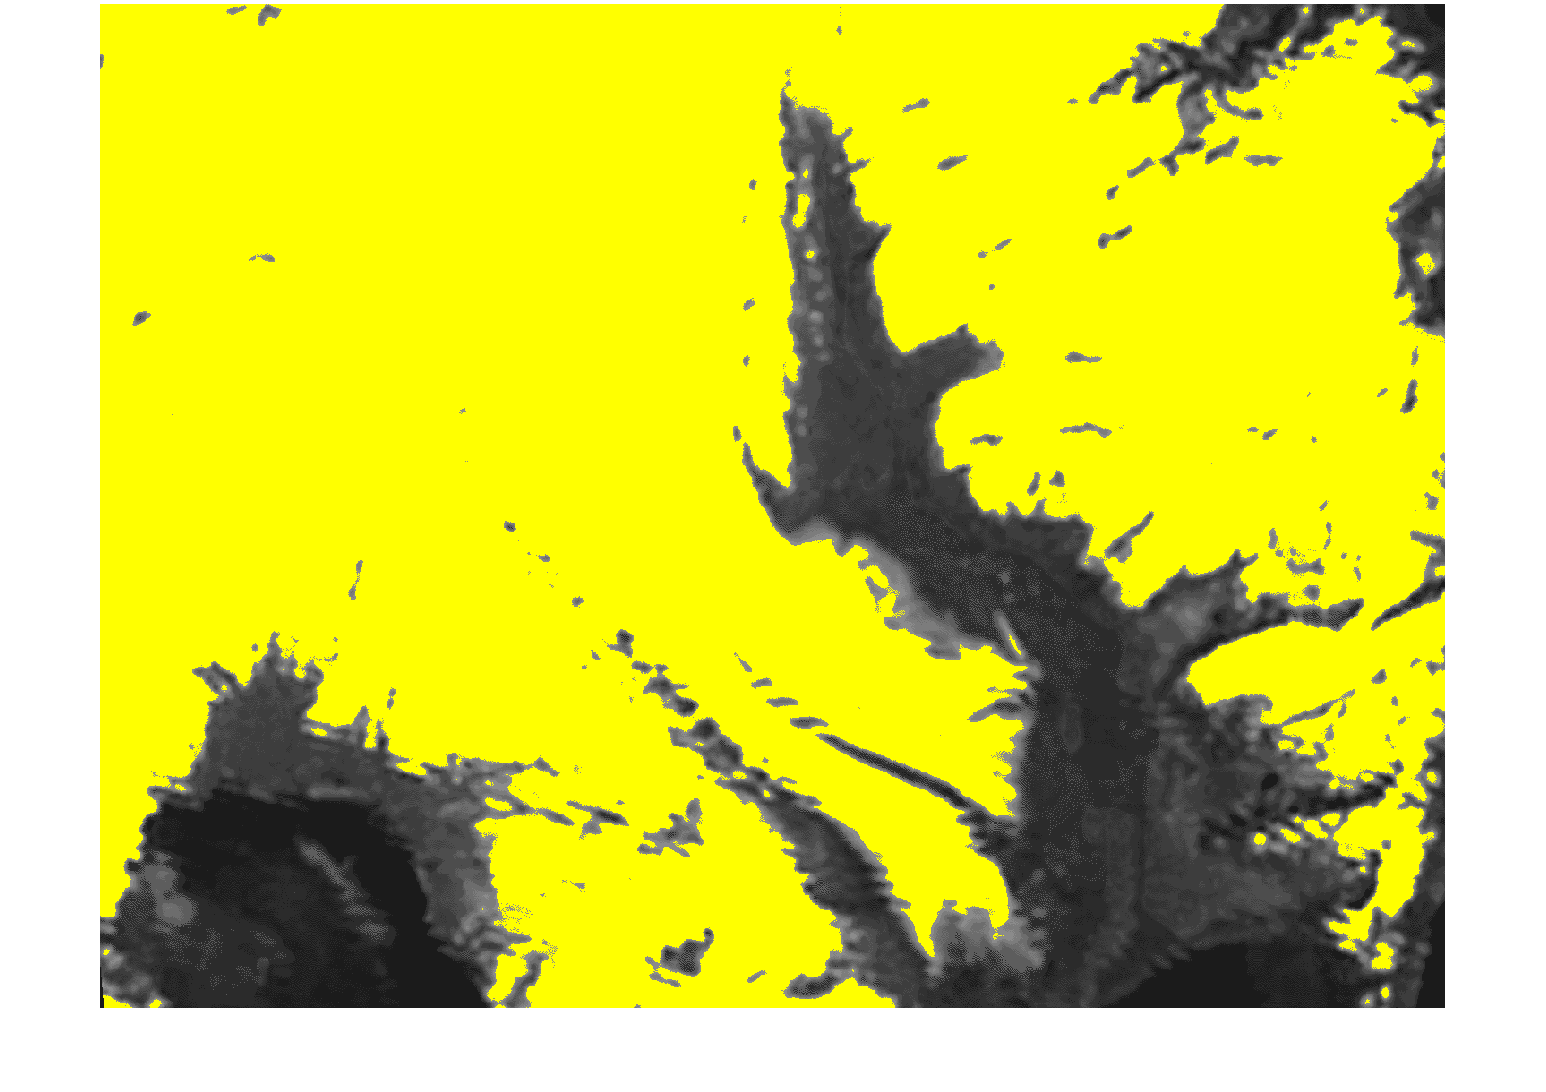

imshow(glacier)

 可以看到，黃色區域就是 mask = True 的區域，也就是冰塊出現的區域

所以，如果我想看，不是冰塊的區域，那就用 `~mask` 就好

non_glacier = imoverlay(gs1980, ~bw1980);

non_glacier = 1121×1502×3 uint8 array
non_glacier(:,:,1) =

   220   220   232   220   232   220   232   220   232   220   232   220   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   232   220   232   232   220   220   232   220   232   220   232   232   232   232   232   232   232   232   239   239   239   244   244   247   247   247   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   249   247   244   239   232   232   232   220   232   220   220   220   220   232   232   232   220   232   232   232   232   220   232   220   220   220   220   220   220   232   220   232   232   232   232   232   232   232   220   220   220   220   203   203   203   203   203   203   203   203   170   189   189   170   189   170   170   1

imshow(non_glacier)

最後，我知道 ~bw1980 表示1980年時，非冰塊的區域

那我如果把它覆蓋到 2011 的照片上，我就可以比對，非冰塊的區域是否變大 (更多冰塊融化掉了)

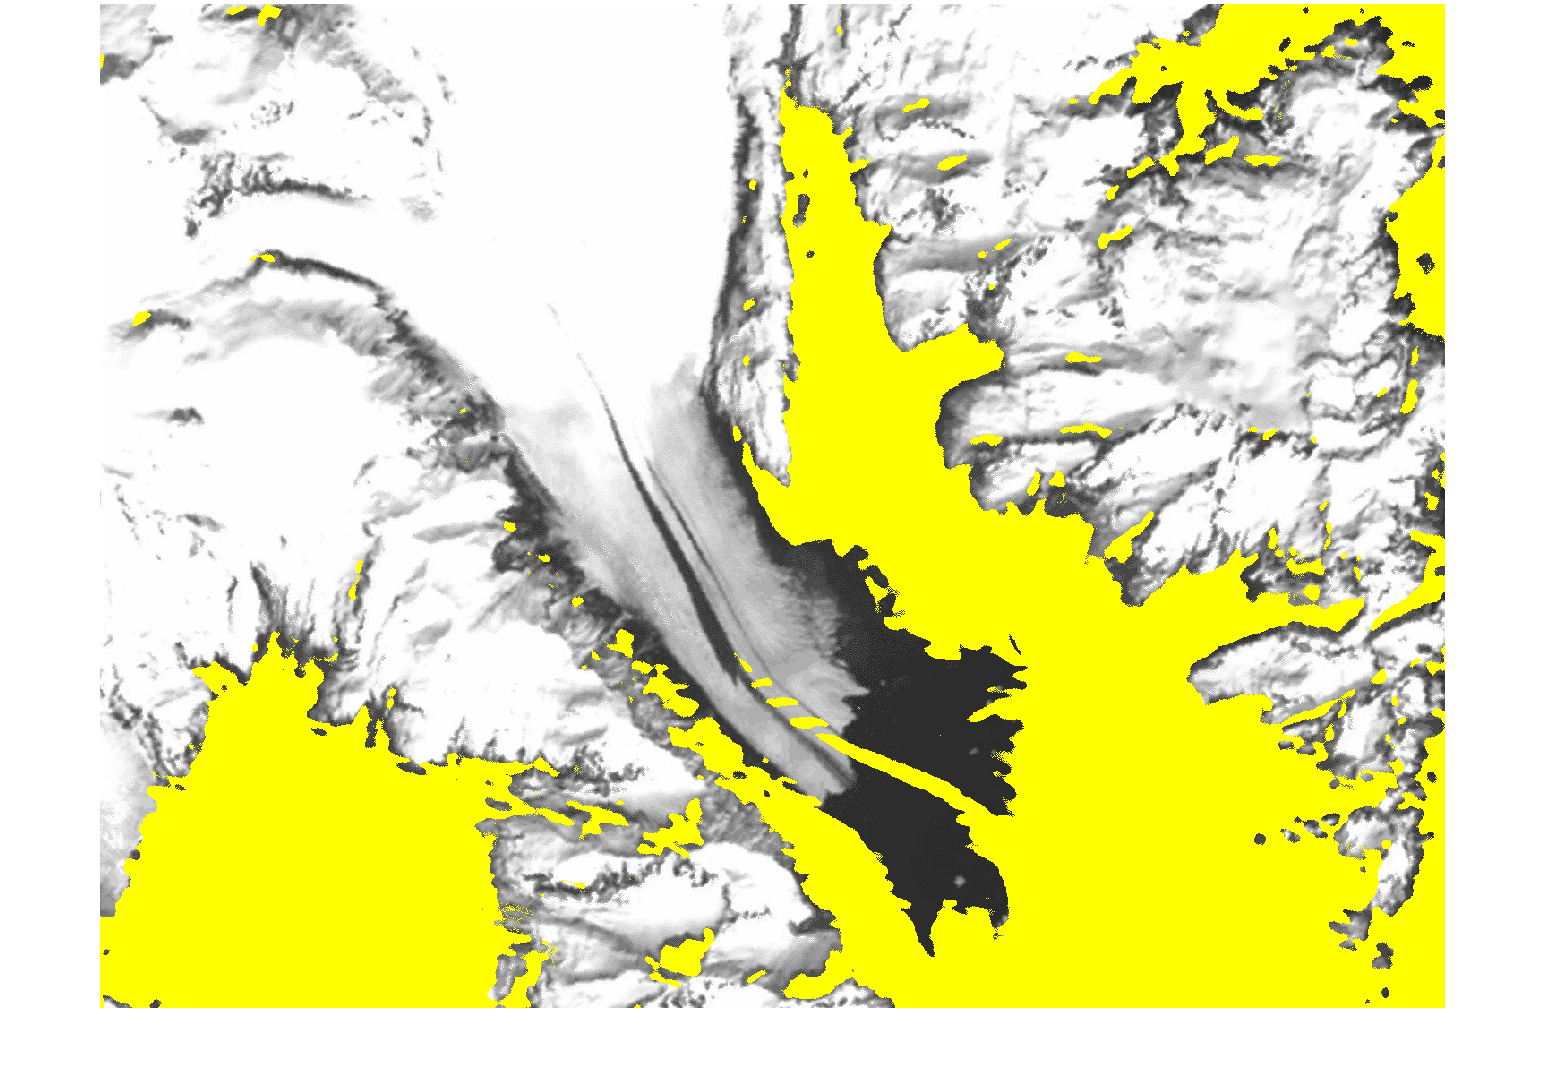

coastline1980 = imoverlay(gs2011,~bw1980);
imshow(coastline1980)

從圖中可以看到，底圖是 2011 的影像，白色是冰川的區域，黑色是水或陸地，黃色是1980的水或陸地。所以看到黃色區域以外的黑色部分，就是新融化的區域。